For this first question, we will demonstrate the second order recipe function on two test cases.

Our first test case involves solving y'' + 2y' + Ky = cos(tau) where y(0) = 0 and dy/dtau(0) = Vo. 

To check the recipe, we will plot the closed-form solution against the output of the second order recipe. 

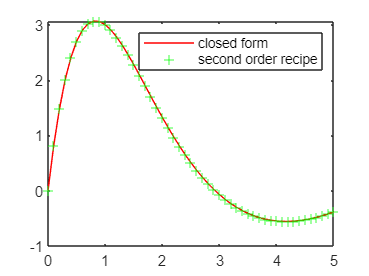

tt = 0:1/10:5; K = min([9 2 3]); V0 = max([5 9 5]);
closed_form_y = exp(-tt).*((42/5)*sin(tt)-(1/5)*cos(tt))+(2/5)*sin(tt)+(1/5)*cos(tt);
y = second_order_recipe([1 2 K], @(x) cos(x), 0, V0, tt);
plot(tt, closed_form_y, '-r', tt, y, '+g')
legend('closed form', 'second order recipe')

For our second test case, we will solve x'' + 2x' + 5x = e^(-tau)*sin(2*tau); x(0) = x0 and dx/dtau(0) = a0.

To check this against the recipe, we will again plot the closed-form solution against the output of the second order recipe.

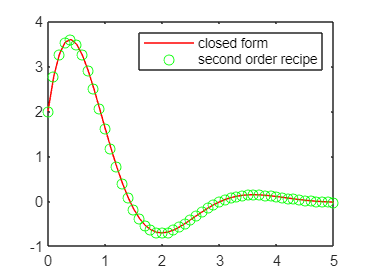

tt = 0:1/10:5; x0 = min([2 3 5]); a0 = max([5 9 5]);
closed_form_x = exp(-tt).*((5.5625)*sin(2*tt)+2*cos(2*tt))+(1/16).*exp(-tt).*(sin(2*tt)-4*tt.*cos(2*tt));
x = second_order_recipe([1 2 5], @(x) exp(-x).*sin(2*x), x0, a0, tt);
plot(tt, closed_form_x, '-r', tt, x, 'og')
legend('closed form', 'second order recipe')

Finally, we will plot y(tau) and x(tau) and the roots for when y(tau)=x(tau) on our final graph on the interval [0,5].

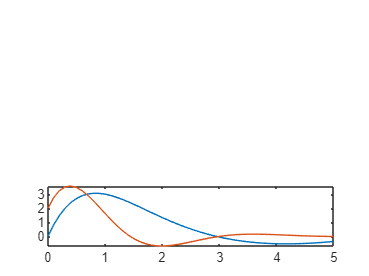

tt = 0:1/10:5; 
subplot(3, 1, 3)
plot(tt, y, tt, x)

HW1_Q2_vjp(@(t) closed_form_y(t),@(t)closed_form_x(t), 2)

Array indices must be positive integers or logical values.

Error in question1_HW2 (line 14)
HW1_Q2_vjp(@(t) closed_form_y(t),@(t)closed_form_x(t), 2)

Error in HW1_Q2_vjp>@(x)f(x)-g(x) (line 8)
fun=@(x) f(x)-g(x);

Error in HW1_Q2_vjp (